clear all; close all; clc;

% NEL FILE IMPORTATO SONO PRESENTI LE POSIZIONI ANGOLARI ASSUNTE DA CIASCUN
% GIUNTO DURANTE LA REGISTRAZIONE DEI FILE DI LOGS CON GIULIA PER
% REGISTRARE LE NUOVE TRAIETTORIE DA METTERE SU FLOATEVO

filename = 'ex_trsp_habd30.xcs';
data = load(filename);

PS = PLOT_STANDARDS(); % Assuming PLOT_STANDARDS defines your color scheme.

time = data(:, 1);
joint_angles = data(:, 2:end);
J1 = data(:, 2);
J2 = data(:, 3);
J3 = data(:, 4);
J4 = data(:, 5);
J5 = data(:, 6);
J6 = data(:, 7);
J7 = data(:, 8);

% J6 is the 1st one to move in the horizontal abduction hence its 1st change is the one of the initial time
indexStart_Go = 1;
while (J6(indexStart_Go) == J6(indexStart_Go + 1))
    indexStart_Go = indexStart_Go + 1;
end
initialTime_Go = time(indexStart_Go); % sec

% Find indices corresponding to endTime_Return
indexEnd_Return = 513;
endTime_Return = time(indexEnd_Return);

% Select the time and joint angles within the interval
interval_time = time(indexStart_Go:indexEnd_Return);
interval_angles = joint_angles(indexStart_Go:indexEnd_Return, :);

% Shift the time axis by initialTime_Go
shifted_time = interval_time - initialTime_Go;

% Font settings
font_name = 'Times'; % Font name
font_size = 60; % Font size

% Definisco i titoli specifici per ogni joint
titles = {...
    'J1 Trajectory - H. Abd 30°', ...
    'J2 Trajectory - H. Abd 30°', ...
    'J3 Trajectory - H. Abd 30°', ...
    'J4 Trajectory - H. Abd 30°', ...
    'J5 Trajectory - H. Abd 30°', ...
    'J6 Trajectory - H. Abd 30°', ...
    'J7 Trajectory - H. Abd 30°'};

% Dimensioni desiderate della figura (larghezza maggiore rispetto all'altezza)
width = 90;  % in centimeters
height = 20;  % in centimeters

% Positione della linea tratto-punto (metà del tempo)
line_position = (shifted_time(1) + shifted_time(end)) / 2;

% Plot ogni joint individualmente in una nuova finestra
num_joints = size(interval_angles, 2);

for i = 1:num_joints
    figure; % Crea una nuova finestra per ciascun joint

    % Modifica le dimensioni della figura per renderla più larga che alta
    set(gcf, 'Units', 'centimeters', 'Position', [0, 0, 80, 30]); % [left, bottom, width, height]
    
    % Imposta la dimensione di esportazione per fare in modo che il salvataggio
    % avvenga con la dimensione desiderata
    set(gcf, 'PaperUnits', 'centimeters');
    set(gcf, 'PaperPosition', [0, 0, width, height]);

    % Crea il plot
    plot(shifted_time, interval_angles(:, i), 'LineWidth', 8, 'Color', PS.Orange2);
    
    % Aggiungi la linea tratto-punto in corrispondenza del tempo centrale
    h_line = xline(line_position, '--', 'LineWidth', 8, 'Color', PS.DRed2);

    % Imposta titolo e assi
    title(titles{i}, 'FontName', font_name, 'FontSize', font_size);
    xlabel('Time [s]', 'FontName', font_name, 'FontSize', font_size);
    ylabel(['\theta_{J', num2str(i), '}(t) [rad]'], 'FontName', font_name, 'FontSize', font_size); % Specific ylabel for each joint
    
    % Set the font properties for axes
    ax = gca; % Get current axis
    ax.FontName = font_name; % Set font name
    ax.FontSize = font_size; % Set font size

    % Imposta i tick sugli assi con una sola cifra decimale
    ax.YTickLabel = num2str(get(gca, 'YTick')', '%.1f'); % Set Y axis ticks with 1 decimal place
    
    grid on;
    
    % Aggiungi la legenda per la linea tratto-punto
    legend(h_line, 'Middle Pos.', 'FontName', font_name, 'FontSize', font_size, 'Location', 'northeast');

    % Salva il grafico come file SVG con dimensioni specifiche
    filename = ['J', num2str(i), '_original30.svg'];
    print(gcf, filename, '-dsvg');
end

**Initial and Final position of each Joint (only Go)**

initial_positions = interval_angles(1,:) %rad

initial_positions =     0.0290   -1.5510    0.0280    2.5040   -1.0640    2.1450   -0.3460


startPosJ1 = initial_positions(1);
startPosJ2 = initial_positions(2);
startPosJ3 = initial_positions(3);
startPosJ4 = initial_positions(4);
startPosJ5 = initial_positions(5);
startPosJ6 = initial_positions(6);
startPosJ7 = initial_positions(7);

**Go trajectory**

% Find the time index where J1 reaches its maximum (end of the go movement)
[~, indexMax_J1] = max(interval_angles(:, 1))

indexMax_J1 = 228

timeMax_J1 = shifted_time(indexMax_J1)

timeMax_J1 = 4.5430

go_time = shifted_time(1:indexMax_J1);
go_angles = interval_angles(1:indexMax_J1, :);

final_positions = interval_angles(indexMax_J1,:) %rad

final_positions =     0.2590   -1.5550    0.2530    2.0210   -0.8070    0.7690   -0.1390


endPosJ1 = final_positions(1);
endPosJ2 = final_positions(2);
endPosJ3 = final_positions(3);
endPosJ4 = final_positions(4);
endPosJ5 = final_positions(5);
endPosJ6 = final_positions(6);
endPosJ7 = final_positions(7);

maxPosJ6 = startPosJ6

maxPosJ6 = 2.1450

minPosJ6 = J6(indexMax_J1)

minPosJ6 = 0.9540

**Linear Interpolation J6**

% Find the indices for time 0 and 3.1801 (end_time) sec
start_time = 0;
end_time = timeMax_J1*0.7;

start_index = find(go_time >= start_time, 1, 'first');
end_index = find(go_time <= end_time, 1, 'last');

% Interpolation data
x = go_time(start_index:end_index); % take the time interval within the shifted one, for only the go trajectory
y = go_angles(start_index:end_index, 6); % J6 angles

% Coeff of interpolation line
p6 = polyfit(x, y, 1); % Linear fit

**Go trajectories in function of J6**

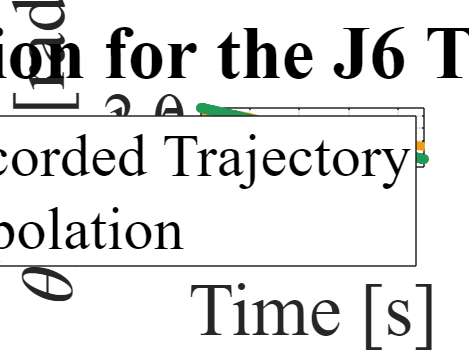

% 5th Polynomial fit for each joint wrt J6
go_fit_results = cell(num_joints, 1);
go_fitted_angles(:,6) = polyval(p6, go_time);
for i = 1:num_joints
    if i == 6
        go_fit_results{i} = p6;
    else
        p = polyfit(go_fitted_angles(:,6), go_angles(:, i), 5);
        go_fit_results{i} = p;
        go_fitted_angles(:, i) = polyval(p, go_fitted_angles(:,6));
    end
end

% Plot interpolating line for J6
figure;

% Imposta la dimensione di esportazione per fare in modo che il salvataggio
% avvenga con la dimensione desiderata

% Dimensioni desiderate della figura (larghezza maggiore rispetto all'altezza)
width = 90;  % in centimeters
height = 30;  % in centimeters

set(gcf, 'PaperUnits', 'centimeters');
set(gcf, 'PaperPosition', [0, 0, width, height]);

plot(go_time, go_angles(:, 6), '-', 'DisplayName', 'Original Recorded Trajectory', 'Color', PS.Orange2, 'LineWidth', 8);
grid on;
hold on;

plot(go_time, go_fitted_angles(:,6), 'DisplayName', 'Linear Interpolation', 'LineWidth', 8, 'LineStyle', 'none', 'Marker', '.', 'MarkerSize', 27, 'MarkerEdgeColor', PS.Green3, 'MarkerFaceColor', PS.Green3);
xlim([0 max(go_time)]);
xlabel('Time [s]', 'FontName', font_name, 'FontSize', font_size);
ylabel('\theta_{J6}(t) [rad]', 'FontName', font_name, 'FontSize', font_size);
xticks(0:1:max(go_time));
yticks(0:0.5:max(go_angles(:,6)));

title('Linear Interpolation for the J6 Trajectory - H. Abd. 30°', 'FontName', font_name, 'FontSize', font_size);
legend;

% Set the font properties for axes
ax = gca; % Get current axis
ax.FontName = font_name; % Set font name
ax.FontSize = font_size; % Set font size

% Imposta i tick sugli assi con una sola cifra decimale
ax.YTickLabel = num2str(get(gca, 'YTick')', '%.1f'); % Set Y axis ticks with 1 decimal place

% Salva il grafico come file SVG con dimensioni specifiche
filename = ['J6_interp30.svg'];
print(gcf, filename, '-dsvg');

% Plot original and fitted trajectories for go
for i = 1:num_joints
    
    figure;

    % Modifica le dimensioni della figura per renderla più larga che alta
    set(gcf, 'Units', 'centimeters', 'Position', [0, 0, 80, 30]); % [left, bottom, width, height]
    
    % Imposta la dimensione di esportazione per fare in modo che il salvataggio
    % avvenga con la dimensione desiderata
    set(gcf, 'PaperUnits', 'centimeters');
    set(gcf, 'PaperPosition', [0, 0, width, height]);

    plot(go_angles(:,6), go_angles(:, i), '-', 'DisplayName', 'Original w.r.t. \theta_{J6}', 'Color', PS.Blue4, 'LineWidth', 8);
    grid on;
    hold on;
    plot(go_fitted_angles(:,6), go_fitted_angles(:, i), 'LineStyle', 'none', 'Marker', 'o', 'MarkerSize', 17, 'MarkerEdgeColor', PS.Red5, 'MarkerFaceColor', PS.Red1, 'DisplayName', 'Interpolation w.r.t. \theta_{J6} Linear');
    title(['J', num2str(i), ' - 5^{th} degree Polynomial Interpolation w.r.t. \theta_{J6} - H. Abd. 30°'], 'FontName', font_name, 'FontSize', font_size);

    xlabel('\theta_{J6} [rad]',  'FontName', font_name, 'FontSize', font_size);
    ylabel(['\theta_{J', num2str(i), '}(\theta_{J6}) [rad]'], 'FontName', font_name, 'FontSize', font_size); % Specific ylabel for each joint
    xlim([minPosJ6 maxPosJ6]);
    legend('FontName', font_name, 'FontSize', font_size, 'Location', 'best');
    
   
    % Set the font properties for axes
    ax = gca; % Get current axis
    ax.FontName = font_name; % Set font name
    ax.FontSize = font_size; % Set font size 

    % Imposta i tick sugli assi con una sola cifra decimale
    % Imposta i tick sugli assi con una sola cifra decimale
    ax.XTickLabel = num2str(get(gca, 'XTick')', '%.1f'); % Set X axis ticks with 1 decimal place
    ax.YTickLabel = num2str(get(gca, 'YTick')', '%.2f'); % Set Y axis ticks with 1 decimal place

    % Salva il grafico come file SVG con dimensioni specifiche
    filename = ['J', num2str(i), '_5thInterp30.svg'];
    print(gcf, filename, '-dsvg');
end

% % Plot original and fitted trajectories for go
% figure;
% for i = 1:num_joints
%     subplot(num_joints, 1, i);
%     plot(go_time, go_angles(:, i), 'o', 'DisplayName', 'Original Go Data');
%     hold on;
%     plot(go_time, go_fitted_angles(:, i), '-', 'DisplayName', '5th Degree Polynomial Go Fit', 'LineWidth', 2);
%     title(['Joint ', num2str(i), ' - Go']);
%     sgtitle('Go - Poly5 joint trajectories')
%     xlabel('Time (s)');
%     ylabel(['\theta_{J', num2str(i), '}( \theta_{J6} ) [rad]'], 'FontName', font_name, 'FontSize', font_size); % Specific ylabel for each joint
%     legend;
%     grid on;
% end
go_fitted_angles_J6 = go_fitted_angles(:,6);
go_fitted_angles_J4 = go_fitted_angles(:,4);

**Return in function of J6**

% return_time = flipud(go_time);
% return_fitted_angles = flipud(go_fitted_angles);
% return_angles = flipud(go_angles);
% 
% % Calcolo dei polinomi di 5° grado per la traiettoria di ritorno usando la traiettoria interpolante di J6
% return_fit_results = cell(num_joints, 1);
% return_fitted_angles = flipud(go_fitted_angles)
% for i = 1:num_joints
%     if i == 6
%         return_fit_results{i} = p6;
%     else
%         p = polyfit(return_fitted_angles(:,6), return_angles(:, i), 5);
%         return_fit_results{i} = p;
%         return_fitted_angles(:, i) = polyval(p, return_fitted_angles(:,6));
%     end
% end
% 
% % Plot delle traiettorie originali e approssimate per il ritorno
% figure;
% for i = 1:num_joints
%     subplot(num_joints, 1, i);
%     plot(return_time, return_angles(:, i), 'o', 'DisplayName', 'Original Return Data');
%     hold on;
%     plot(return_time, return_fitted_angles(:, i), '-', 'DisplayName', '5th Degree Polynomial Return Fit', 'LineWidth', 2);
%     title(['Joint ', num2str(i), ' - Return']);
%     sgtitle('Return - Poly5 joint trajectories');
%     xlabel('Time (s)');
%     ylabel('Angle (rad)');
%     legend;
%     grid on;
% end

The Poly5 coeff are the same for both Go and Return since now all teh joint are computed as function of the J6, hence tehy are time independent.

This means that we need just one Poly5 for each joint!

In FloatEVO sw this coeff are written in the converse order wrt matlab

go_fit_results

go_fit_results = 7×1 cell array
    {[ -0.3392 2.3298 -5.8308 6.4320 -3.1323 0.7819]}
    {[ 0.0057 -0.0398 0.1063 -0.1336 0.0781 -1.5677]}
    {[ -0.3735 2.4713 -5.9359 6.2525 -2.9005 0.7155]}
    {[0.9462 -6.4172 15.8922 -17.4134 8.4086 0.6109]}
    {[-0.3308 2.2960 -5.7664 6.2902 -2.9636 -0.3187]}
    {[                               -0.4423 2.3014]}
    {[ 0.2481 -1.5404 3.4779 -3.5508 1.5853 -0.3935]}


% P is a row vector of length N+1 containing the polynomial coefficients 
% in descending powers, P(1)*X^N + P(2)*X^(N-1) +...+ P(N)*X + P(N+1).

% return_fit_results

**A) Gaussian Resistive Torque**

% % Gaussian parameters
% desired_max_torque = 7.5; % Nm 
% sigma = 0.5; % rad 
% q6_range = [minPosJ6, maxPosJ6]; % rad
% mean_shift = (minPosJ6 + maxPosJ6) / 2; % rad
% 
% % J6 positions in the given interval
% q6_values = linspace(minPosJ6, maxPosJ6, 1000);
% 
% % Needed amplitue to compute the max desired torque as the peak
% % peak value for a Gaussian centred in mean_shift and with st dev sigma
% max_pdf_value = (1/(sigma * sqrt(2 * pi))) * exp(-0.5 * ((mean_shift - mean_shift) / sigma)^2)
% % Scale factor to be multiplied to the gaussian in order to obtain a peak
% % exactly where desired (in the standardized distribution it is 1)
% torqueAmplitude = desired_max_torque / max_pdf_value
% % Resistive Gaussian Torque Profile
% resTorque = torqueAmplitude * (1/(sigma * sqrt(2 * pi))) * exp(-0.5 * ((q6_values - mean_shift) / sigma).^2);
% 
% % Find the position and the value of the max Torque
% [max_torque, max_index] = max(resTorque);
% max_q6 = q6_values(max_index);
% 
% % Plot Gaussian profile
% figure;
% plot(q6_values, resTorque, 'LineWidth', 2);
% hold on;
% title('Resistive Torque Profile');
% xlim([minPosJ6, maxPosJ6]);
% xlabel('J6 Angle [rad]');
% ylabel('Resistive Torque [Nm]');
% 
% % Plot vertical line corresponding to the max resistance pos
% y_limits = ylim;
% plot([max_q6, max_q6], y_limits, 'r--', 'LineWidth', 1.5); % Linea verticale
% 
% % Highlight the max resTorque 
% plot(max_q6, max_torque, 'ro', 'MarkerSize', 10, 'LineWidth', 2);
% grid on;
% 
% % Adjust the grid in smaller interval
% xticks(linspace(min(q6_values), max(q6_values), 10)); 
% yticks(linspace(min(resTorque), max(resTorque), 10));
% legend('Gaussian Resistive Torque', 'Max Resistance Position J6', 'Max Resistance Position');

**Normalize the time interval in [0,1] s**

- Keep J2, J7 fixed at the initial angle;

- For J1, J3 only one trajectory;

- Store the initial position of each joint;

- Consider just the J1 to split Go and Return (max extension). Then, consider only the Go and going backward compute the Return to have a continuous trajectory.

- Consider the straight line from 0 to 0.7 of J6 in order to have a linear correlation between J1, J4 and J5.

- Then compute the 5th order Poly of J1, J4, J5 as function of that line og J6 in order to reach a certain target and easily define the start and stop of the straight line of J6.